% This script runs beadSLAM. It has been put together quickly, and is not a
% great way to code.

## Specify the scenario

% Plot outputs each timestep. Graphically useful, but can really SLOW down
% the program. Up top because it gets changed a lot!
showStepByStepResults = true;

% Motion model
% 0 - random walk
% 1 - oscillate
% 2 - slowly crawl to the middle
motionFlag = 1;

% Observation model
% 0 - observe nothing
% 1 - observe everything
% 2 - observe subset of landmarks (1.5 times extent / number of landmarks)
% 3 - observe small window
observationFlag = 2;

% Cross correlations
% 0 - drop
% 1 - keep
correlationsFlag = 1;

% Step flag for lectures
% 0 - keep running
% 1 - step through each step separately
lectureScenario = 1;
lecturePause = 1;


## Specify the scenario parameters

% Map specification
% Number of landmarks M
numberOfLandmarks = 20;

% Extent over which they will be distributed [-extent, extent]
extent = 100;

% Number of timesteps
numberOfTimeSteps = 64000;

% Length of time between each time step
dT = 1;

% Process noise
q = 1e-4;

% Observation noise. The bigger the value, the slower the convergence.
R = 4;

% Output options

## Generate various parameters

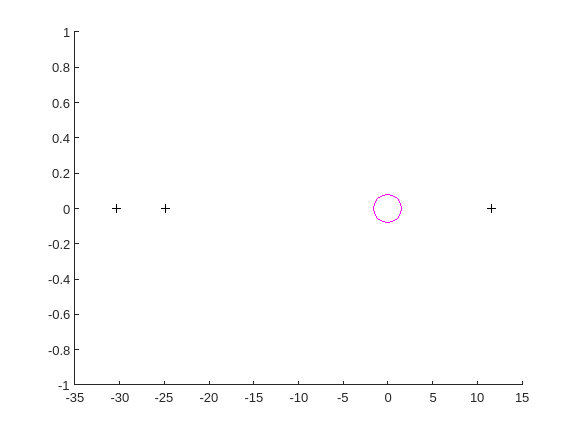

% If we are doing the lecture, we overwrite the above!
% in lecture we had 3 landmarks only
if (lectureScenario == 1)
    motionFlag = 0;
    observationFlag = 1;
    % we see all landmarks at all times
    % becasue later on we set range distance d=100000
    correlationsFlag = 1;
    numberOfLandmarks = 3;
    showStepByStepResults = false;
end

if (lecturePause == 1)
    showStepByStepResults = true;
end

% If we are storing some convergence stats, do it

% Create the landmarks
landmarks = extent * (rand(numberOfLandmarks, 1) - 0.5);
%landmarks = extent * ([1:numberOfLandmarks]' / numberOfLandmarks - 0.5);

% Create the vehicle process model
F = [1 dT;0 1];
G = [dT^2/2; dT];
Q = q * [dT^3/3 dT^2/2;dT^2/2 dT];

% Observation distance
if (observationFlag == 0)
    d = 0;
elseif (observationFlag == 1)
    d = 1e6;
    % we see all landmarks all the time
elseif (observationFlag == 2)
    d = 1.5 * extent / numberOfLandmarks;
else
    d = 3;
end

% Create the square root of the covariance matrices. These are used for
% sampling in the simulator
QSqrtm = sqrtm(Q);
RSqrtm = sqrt(R);

% The true vehicle initial conditions
% these are updated using the process model
xTrue = zeros(2, 1);

% The initial conditions - in this case, we have no landmarks and no
% vehicle state. So S = [0; 0] the pos and speed of robot being 0
% sEst is a column vector
% Remember that "x" is the vehicle state and "s" is the SLAM
% system state, including the vehicle and all the landmarks.
sEst = zeros(2, 1);
PEst = zeros(2, 2);
slamMapLandmarkIDs = [];

% Arrays to store the ground truth, the estimated value of the filter and
% the covariances. We fill these with NaNs to account for the fact that
% different landmarks are initialised at different times.

% For state estimates we store the vector directly. For the covariance
% matrices, we only store the diagonals. Although the off-diagonal
% cross-correlation terms are super important for the operation of the
% filter, there are a lot of them to store and they are difficult to
% meaningfully visualise. As a result, we store: 
% (i) the left most column of the covariance matrix 
% (correlation of vehicle position with landmark positions) and 
% (ii) the third column of the covariance matrix which
% gives a slice between the vehicle position and landmark positions.

maxNumberOfStates = 2 + numberOfLandmarks;

sTrueStore = NaN(maxNumberOfStates, numberOfTimeSteps);
sEstStore = NaN(maxNumberOfStates, numberOfTimeSteps);
PssEstStore = NaN(maxNumberOfStates, numberOfTimeSteps);
PxmEstStore = NaN(maxNumberOfStates, numberOfTimeSteps);
PmmEstStore = NaN(maxNumberOfStates, numberOfTimeSteps);

% Setup the plotting for the scenario
if (showStepByStepResults == true)
    figure(1)
    clf
    hold on
    truth.HLandmarks = plot(landmarks, zeros(numberOfLandmarks, 1), 'k+');
    truth.HVehicle = plot(xTrue(1), 0, 'ko', 'MarkerSize', 20);
    %truth.HLandmarkObs = plot(xTrue(1), 0, 'k+', 'MarkerSize', 20);
    truth.HLandmarkObs2 = NaN(1, numberOfLandmarks);
    for l = 1 : numberOfLandmarks
        truth.HLandmarkObs2(l) = text(NaN, NaN,'\uparrow', 'color' ,[0.8 0.5 0.5],'FontWeight','bold', 'Fontsize', 16);
    end
    
    % Plot the vehicle estimate
    estimate.HVehicle = plot(sEst(1), 0, 'mo', 'MarkerSize', 20);
    estimate.HVehicleCov = plot(NaN, NaN, 'm', 'LineWidth', 2);
    
    % Plot the landmark estimates
    estimate.HLandmarks = plot(NaN, NaN, '+', 'Color', 'm');
    estimate.HLandmarkCovs = plot(NaN, NaN, 'Color', 'm', 'LineWidth', 2);
end


if (lecturePause == 1)
    sEst
    PEst
    % pause
    % fprintf("Press a key to continue. Pause 1")
    % pause until any key is pressed in coomand window
end

sEst =      0
     0


PEst =      0     0
     0     0


## Run the main loop

a= 1

a = 1

for step = 1 : numberOfTimeSteps
    
    % Print progress
    if (rem(step, 100) == 0)
    % rem(a,b) returns the remainder after division of a by b
    % print values after every 100 steps
        fprintf('%04d / %04d\n', step, numberOfTimeSteps);
    end
    
    % Execute the simulator, and for that we need the control input
    % depending on our choice we set it values
    
    if (step < 20)
        u = 0;
    else
        % Pick the control input strategy
        if (motionFlag == 0)
            u = 0;
        elseif (motionFlag == 1)
            u = - (xTrue(1) < 0) * (0.001 * xTrue(1));
        elseif (motionFlag == 2)
            u = -0.00001 * xTrue(1);
        end
    end
    
    % If the platform is leaving the map, over ride the above and force it
    % back in by changing control inputs
    if (xTrue(1) > 0.555 * extent)
        u = 0.001 * (0.555*extent - xTrue(1));
    elseif (xTrue(1) < -0.555 * extent)
        u = 0.001 * (0.555*extent - xTrue(1));
    end
    % the control input u has been set. Now we use the process model





    % Simulate the movement of the robot
    % using process model
    xTrue = F * xTrue + G * u + QSqrtm * randn(2, 1); % 2,1
    


    % Work out all the visible landmarks
    dX = landmarks - xTrue(1); % M,1 matrix of all landmarks
    visibleLandmarkIDs = find(abs(dX) < d); % P, 1 matrix where 0<=P<=M depending on the range
    % index of landmarks in range
    z = dX(visibleLandmarkIDs) + RSqrtm * randn(size(visibleLandmarkIDs, 1), 1); % P, 1 matrix
    % only take those distances which would be visible and add noise
    




    % Now do the filter update
    
    % Predict. We exploit the fact that only the vehicle is updated to
    % reduce the number of calculations - although we end up having to
    % write more terms down.
    sPred = sEst;
    sPred(1:2) = F * sEst(1:2) + G * u;
    % calculation of xTrue above is similar except the QSqrtm part
    PPred = PEst;
    PPred(1:2, 1:2) = F * PEst(1:2, 1:2) * F' + Q;
    % top left 2,2 block
    PPred(1:2, 3:end) = F * PEst(1:2, 3:end);
    PPred(3:end, 1:2) = PPred(1:2, 3:end)';
    PPred = 0.5 * (PPred + PPred');
    
    if (min(eig(PPred)) < 0)
        keyboard
        % enter debug mode
    end
    
    % Remove cross correlations if desired
    if (correlationsFlag == 0)
        PPred(1:2, 3: end) = 0;
        PPred(3: end, 1:2) = 0;
        PMM = diag(PPred(3:end,3:end));
        PPred(3:end,3:end) = diag(PMM);
    end
    
    
    if (lecturePause == 1)
        sPred
        PPred
        pause
    end
    
    % The partial update updates with the landmarks in the map
    sPartialEst = sPred;
    PPartialEst = PPred;
    











    % First do the update without augmentation.
    % i.e. working with features already in the map
    
    % Find the observed features which are in the map
    [landmarksAlreadyInMapIDs, iA, iB] = intersect(visibleLandmarkIDs, slamMapLandmarkIDs);
    
    % Iterate through the list; this is an inefficient (but easy!) way to
    % code it
    for m = 1 : length(iA)
        H = zeros(1, size(sEst, 1));
        H(1, 1) = -1;
        H(1, 2 + iB(m)) = 1;
        C = PPartialEst * H';
        S = H * C + R;
        W = C / S;
        zPred = H * sPartialEst;
        sPartialEst = sPartialEst + W * (z(iA(m)) - zPred);
        PPartialEst = PPartialEst - W * S * W';



        if (correlationsFlag == 0)
            PPartialEst(1:2, 3: end) = 0;
            PPartialEst(3: end, 1:2) = 0;
            PMM = diag(PPartialEst(3:end,3:end));
            PPartialEst(3:end,3:end) = diag(PMM);
        end
    end
    
    if (min(eig(PPartialEst)) < 0)
        keyboard
    end
    
    if (lecturePause == 1)
        sPartialEst
        PPartialEst
        pause
    end
    












    
    % Now create the new final update
    sEst = sPartialEst;
    PEst = 0.5 * (PPartialEst + PPartialEst');
    
    % Remove cross correlations if desired
    if (correlationsFlag == 0)
        PEst(1:2, 3: end) = 0;
        PEst(3: end, 1:2) = 0;
        PMM = diag(PEst(3:end,3:end));
        PEst(3:end,3:end) = diag(PMM);
    end
    
    % Identify the unprocessed landmarks - these are the new ones we need
    % to add to the map
    [newLandmarkIDs, iA, iB] = setxor(visibleLandmarkIDs, landmarksAlreadyInMapIDs);
    
    % Augment the state
    if (isempty(newLandmarkIDs) == false)
        
        % Update the vector of identities
        slamMapLandmarkIDs = cat(1, slamMapLandmarkIDs, newLandmarkIDs);
        numNewLandmarks = size(newLandmarkIDs, 1);
        
        stateDimension = size(sEst, 1);
        newStateDimension = size(sEst, 1) + numNewLandmarks;
        
        % Create the matrix to augment the state
        A = zeros(newStateDimension, stateDimension);
        A(1:stateDimension, 1:stateDimension) = eye(stateDimension);
        A(stateDimension+1:end, 1) = 1;
        B=zeros(newStateDimension, numNewLandmarks);
        B(newStateDimension-numNewLandmarks+1:end, 1:end) = eye(numNewLandmarks);
        
        % Augment the state. This automatically initialises the landmark
        % and the covariance in one step.
        sEst = A * sEst + B * z(iA);
        PEst = A * PEst * A' + B * R * B';
        
        if (lecturePause == 1)
            sprintf('Added landmarks %d', newLandmarkIDs)
            sEst
            PEst
            pause
        end
    end
    
    if (min(eig(PEst)) < 0)
        keyboard
    end
    
    
    PEst = 0.5 * (PEst + PEst');
    
    % Remove cross correlations if desired
    if (correlationsFlag == 0)
        PEst(1:2, 3: end) = 0;
        PEst(3: end, 1:2) = 0;
        PMM = diag(PEst(3:end,3:end));
        PEst(3:end,3:end) = diag(PMM);
        PEst
    end
    
    % Store the updates
    
    % Ground truth
    sTrueStore(1:2, step) = xTrue;
    sTrueStore(3:end, step) = landmarks';
    
    % Copy the state estimate over. The mucking around with the indexing is
    % used to put the state estimates in the same place that we can compare
    % directly with the truth.
    sEstStore(1:2, step) = sEst(1:2);
    PssEstStore(1:2, step) = PEst(1:2, 1);
    for m = 1 : size(slamMapLandmarkIDs, 1)
        storeStateIdx = slamMapLandmarkIDs(m) + 2;
        sEstStore(storeStateIdx, step) = sEst(m + 2);
        PssEstStore(storeStateIdx, step) = PEst(m+2, m+2);
        PxmEstStore(storeStateIdx, step) = PEst(1, m+2) / sqrt(PEst(1, 1) * PEst(m+2, m+2));
        PmmEstStore(storeStateIdx, step) = PEst(3, m+2);
    end
    
    % Update graphics
    if (showStepByStepResults == true)
        
        % Update the true vehicle
        set(truth.HVehicle, 'XData', xTrue(1), 'YData', 0);
        
        % Update the observations
        for k = 1 : numberOfLandmarks
            set(truth.HLandmarkObs2(k), 'Position', NaN(1, 3));
        end
        
        for k = 1 : size(visibleLandmarkIDs, 1)
            set(truth.HLandmarkObs2(visibleLandmarkIDs(k)), 'Position', ...
                [z(k)+xTrue(1) -0.05 0]);
        end
        
        % Update the vehicle estimate
        set(estimate.HVehicle, 'XData', sEst(1), 'YData', 0);
        
        % Work out the covariance bound
        stdX = sqrt(PEst(1, 1));
        set(estimate.HVehicleCov, 'XData', sEst(1) + 2 * stdX * [-1 1], 'YData', [0 0]);
        
        % Construct the landmarks
        landmarkX = NaN(1, 2 * length(sEst) - 4);
        landmarkY = zeros(1, 2 * length(sEst) - 4);
        landmarkX(1:2:end) = sEst(3:end);
        set(estimate.HLandmarks, 'XData', landmarkX, 'YData', landmarkY);
        
        landmarkStds = 2 * sqrt(diag(PEst(3:end, 3:end)));
        
        landmarkStdX = NaN(1, 3 * length(sEst) - 6);
        landmarkStdX(1:3:end) = sEst(3:end) - landmarkStds;
        landmarkStdX(2:3:end) = sEst(3:end) + landmarkStds;
        set(estimate.HLandmarkCovs, 'XData', landmarkStdX, 'YData', zeros(1, 3 * length(sEst) - 6));
        
        drawnow
    end
end

## Summary stats

fprintf('Number of initialised landmarks=%d\n', numel(slamMapLandmarkIDs));

## Plot final results

figure(2)
clf
plot(PssEstStore(1:2,:)')
title('Vehicle covariance')

figure(3)
clf
plot(log(PssEstStore(1:2,:))')
title('Log of vehicle covariance')

figure(4)
clf
plot(PssEstStore(3:end,:)')
title('Landmark covariances')

figure(5)
clf
plot(log(PssEstStore(3:end,:))')
title('Log landmark covariances')


figure(6)
clf
plot(PxmEstStore(3:end,:)')
title('Vehicle landmark cross correlations')

figure(7)
clf
plot(PmmEstStore(3:end,:)')
title('Landmark-landmark cross correlations')